## Generate noise

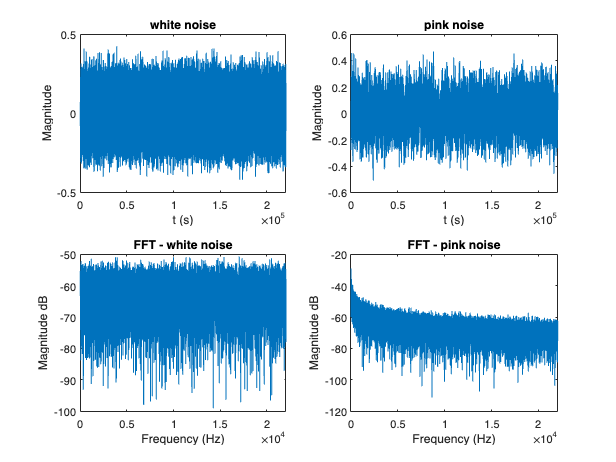

clear;clc;
sig_len_sec = 5;
fs = 44100; % in this file all the fs should be the same, eg. 44100Hz
white_noise = 0.1* randn(sig_len_sec*fs,1);
% audiowrite('White_noise_domo_5s.wav',white_noise,fs);
pink_noise = 3.5* pinknoise(sig_len_sec*fs,1);
% audiowrite('Pink_noise_domo_5s.wav',pink_noise,fs);
N = 44100;          %变换的点数

n = 0:N-1;          %频谱序列

H_wn = fft(white_noise,N);
H_pn = fft(pink_noise,N);
figure
subplot(2,2,1)
plot(white_noise)
xlabel('t (s)')
ylabel('Magnitude')
title('white noise')

subplot(2,2,2)
plot(pink_noise)
title('pink noise')
xlabel('t (s)')
ylabel('Magnitude')

subplot(2,2,3)
% specgram(white_noise)
plot(n/N*fs,db(abs(H_wn)*2/N)); 
xlim([0 fs/2])
title('FFT - white noise')
xlabel('Frequency (Hz)')
ylabel('Magnitude dB')

subplot(2,2,4)
% specgram(pink_noise)
plot(n/N*fs,db(abs(H_pn)*2/N)); 
xlim([0 fs/2])
title('FFT - pink noise')
xlabel('Frequency (Hz)')
ylabel('Magnitude dB')

## Load speech or sound

% load speech signal 
cd '/Users/zhouyiliang/Desktop/work/'
[speech,fs] = audioread('sound_sample/speech1.wav');

## Generate tone 


$$x(t) = a \sin(2\pi\, f\, t)$$


fs = 44100;
a = 0.1; % amplitude
f_2000 = 2000; % 2 kHz
f_800 = 800;
tMax = 3; % 3 sec
% fs = 44100; % sampling frequency
t = 0:1/fs:tMax-1/fs;
t2 = linspace(0, tMax-1/fs, tMax * fs);
x = a * sin(2 * pi * f_2000 * t);
x_800 = a * sin(2 * pi * f_800 * t);
% T = 1/f_800;
% nfft = 256;
% 
% X = fft(x,nfft);
% fasix = linspace(0,fs,256);
% figure
% semilogx(fasix, abs(X) )
% xlim([0,fs/2])
% xlabel('f')


Add amplitue overtime $x_1(t) = a \sin(2\pi\, f\, t) * e^{0.5t}$ (exponatial) $x_2(t) = a \sin(2\pi\, f\, t) * 0.5t$

% we can also add zero before/after the tone
appendedSilenceLenSec = 0.5;
x_1 = x .* exp(1*t);% now this is a row vector, while zeros generate column vector 
x_1 = [zeros(appendedSilenceLenSec*fs,1); x_1'];%before
x_2 = x_800 .* (t);
x_2 = [x_2'; zeros(appendedSilenceLenSec*fs,1)];%after


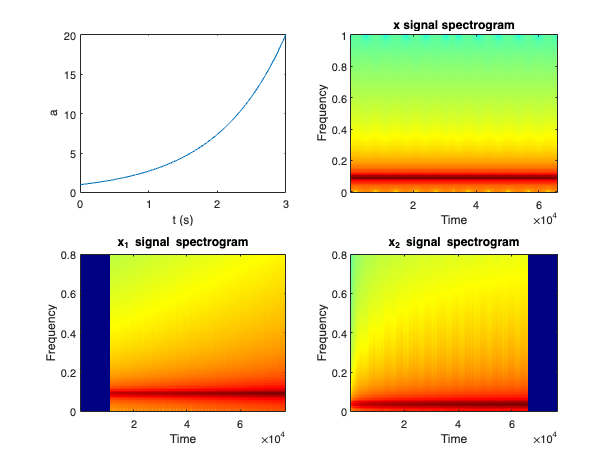


figure
subplot(2,2,1)
plot(t, exp(1*t))
xlabel('t (s)')
ylabel('a')
subplot(2,2,2)
specgram(x)
title('x signal spectrogram')
subplot(2,2,3)
specgram(x_1)
ylim([0 0.8])
title('x_1 signal spectrogram')
subplot(2,2,4)
specgram(x_2)
ylim([0 0.8])
title('x_2 signal spectrogram')

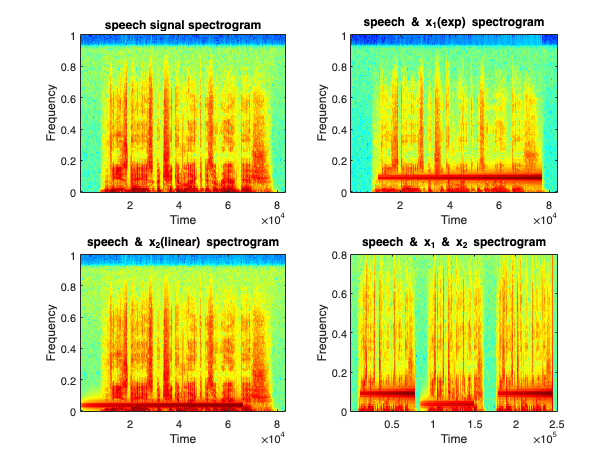

% Add together 
% sound(x,fs);
% keyboard
% sound(x_1,fs);
% keyboard
% sound(x_2,fs);
speech_x_1 = zeros(max(length(x_1),length(speech)),1);
speech_x_1(1:length(x_1),:) = x_1;
speech_x_1(end- length(speech)+1:end,:) = speech + speech_x_1(end- length(speech)+1:end,:);

speech_x_2 = zeros(max(length(x_2),length(speech)),1);
speech_x_2(1:length(x_2),:) = x_2;
speech_x_2(end- length(speech)+1:end,:) = speech + speech_x_2(end- length(speech)+1:end,:);

speech_x_1_tre = [speech_x_1; speech_x_2; speech_x_1];
figure
subplot(2,2,1)
specgram(speech)
title('speech signal spectrogram')
subplot(2,2,2)
specgram(speech_x_1)
title('speech & x_1(exp) spectrogram')
subplot(2,2,3)
specgram(speech_x_2)
title('speech & x_2(linear) spectrogram')
subplot(2,2,4)
specgram(speech_x_1_tre )
ylim([0 0.8])
title('speech & x_1 & x_2 spectrogram')

% sound(speech_x_1_tre,fs);
% audiowrite('sound_output/speech_add_howling_tre2000Hz800Hz2000Hz.wav',speech_x_1_tre,fs)
speech_fyra= [speech; speech_x_1_tre];
% audiowrite('sound_output/speech_add_howling_fyra.wav',speech_fyra,fs)
% addpath('/Users/zhouyiliang/Desktop/work/')
% audiowrite('sound_output/speech_x_1.wav',speech_x_1,fs)
audiowrite('sound_output/speech_x_2.wav',speech_x_2,fs)

## Notch filter design

see doc dsp.NotchPeakFilter 

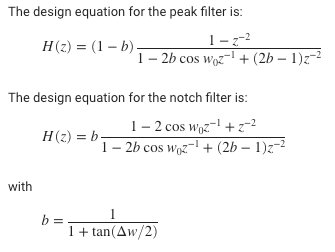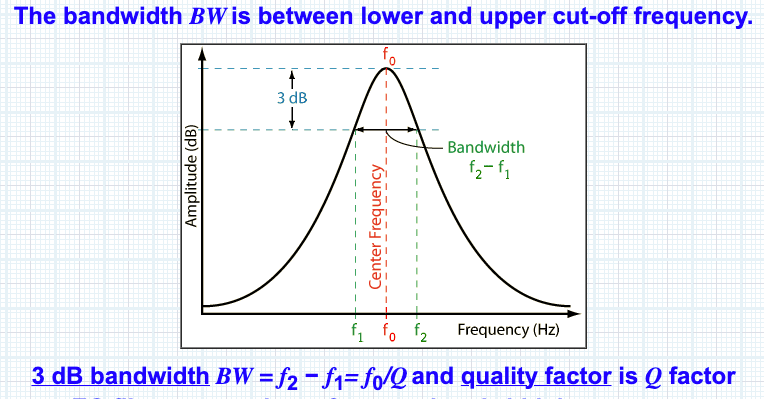

where *ω*0 = 2π*f*0/*f*s is the center frequency in radians/sample (*f*0 is the center frequency in Hz and *f*s is the sampling frequency in Hz). Δ*ω* = 2πΔ*f*/*f*s is the 3 dB bandwidth in radians/sample (Δ*f* is the 3 dB bandwidth in Hz). Note that the two filters are complementary:

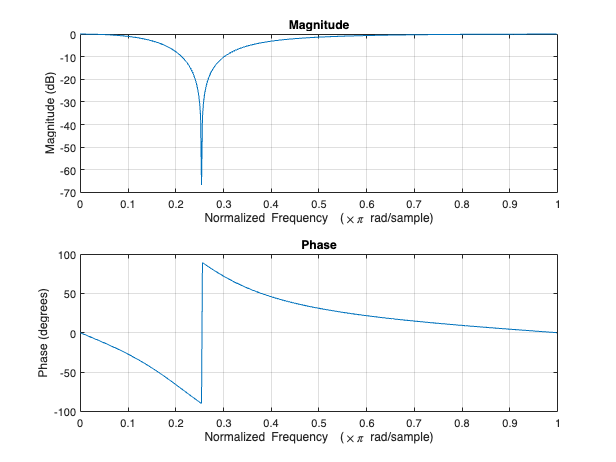

% clear
% design a notch filter with center frequency f_0 = 1000Hz and 3 dB bandwidth dw = f_0/Q
fs = 44100; %sampling rate
f_0 = 5600; %center frequency
Q = 10; %quality factor
% ind = 0;
% for Q = [1 10 100 1000]
%     ind = ind+1;
    dw = f_0/Q; %3 dB bandwidth
    w_0 = 2*pi*f_0/fs;
    b = 1/(1+tan(dw/2));
    notch_b = b * [1, -2*cos(w_0) ,1]; %numerator
    notch_a = [1, -2*b*cos(w_0), 2*b-1]; %denominator 
    peak_b = (1-b) * [1, 0 , -1];
    peak_a = [1 , -2*b*cos(w_0), 2*b-1];
    % Frequency response 
%     figure
%     subplot(2,2,ind)
    freqz(notch_b,notch_a)

% end

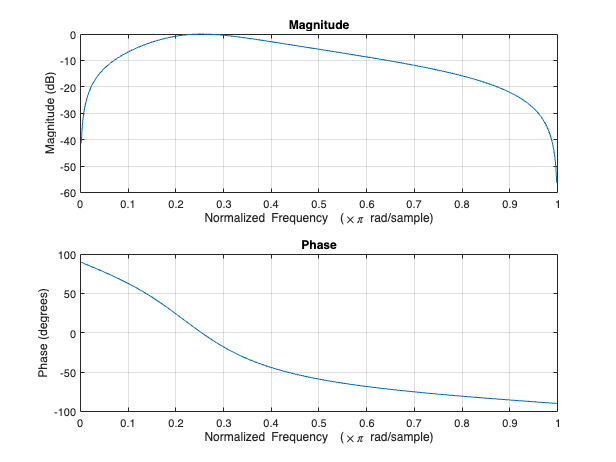

freqz(peak_b,peak_a)

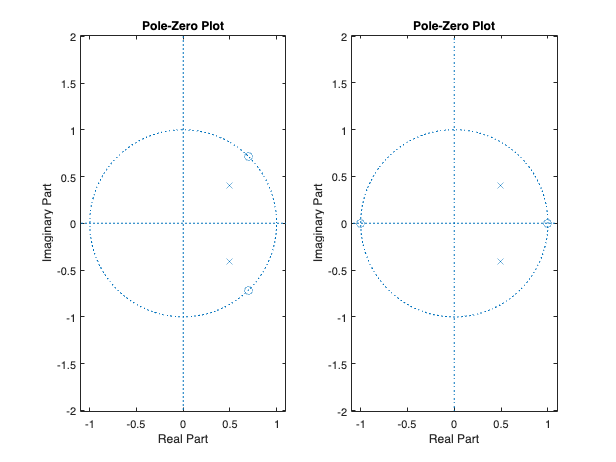

figure 
subplot(1,2,1)
zplane(notch_b,notch_a)
subplot(1,2,2)
zplane(peak_b,peak_a)

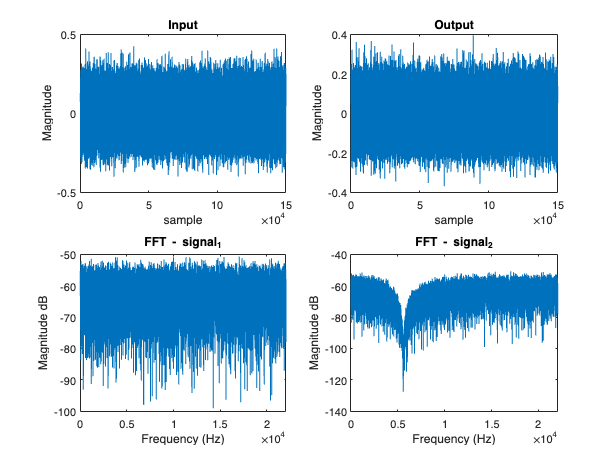

% filter a white noise signal using notch filter
addpath('/Users/zhouyiliang/Desktop/work/Howling_suppression/NHS/user_defined_function')
filtered_signal = add_iir_notch_filter(f_0, Q, fs,white_noise);
plot_2_signal_and_FFT(white_noise, filtered_signal,fs, N);

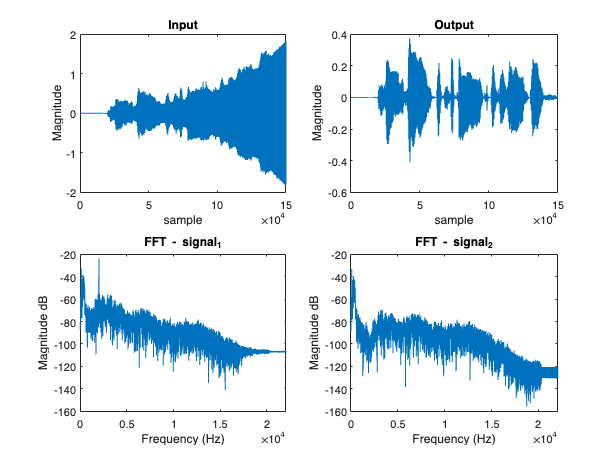

filtered_signal_2 = add_iir_notch_filter(2000, 100, fs,speech_x_1);
plot_2_signal_and_FFT(speech_x_1, filtered_signal_2,fs, N);

%check coefficients of different frequencys
freqs = linspace(0, 44100, 1764);
bs_1 = zeros(length(freqs),3);
as_1 = zeros(length(freqs),3);
flag = zeros(length(freqs),1); 
idx = 1;
for i = freqs
    
    [notch_b,notch_a,peak_b,peak_a] = notch_peak_filter_yl(i, 10, 44100);
%     d = fdesign.notch(2,i, 10);
    bs_1(idx,:) = notch_b;
    as_1(idx,:) = notch_a;
    flag(idx) = isstable(notch_b,notch_a); %check if the iir is stable (1 is stable,0 is unstable)
    idx = idx + 1;
end
stable_fre_idx = find(flag~=0);   % zero position

addpath('/Users/zhouyiliang/Desktop/work/Howling_suppression/NHS/')
available_id = load('stable_fre_idx_notch_q10.mat');

% check if index is 0 then find the nearest 1 
% xxin = 28;
% if flag(xxin) == 0
%     while xxin < length(flag)
%         xxin = xxin + 1;
%         if flag(xxin) == 1
%             break
%         end
%     end
% end


## Adaptive notch filter

clear; clc;
% load signal 
cd '/Users/zhouyiliang/Desktop/work/sound_output'
[Howling_signal,fs] = audioread('sound_output/speech_add_howling_fyra.wav');
f_0 = 2000;
signal = Howling_signal;
% fs = 44100;
% a = 0.1; % amplitude
% f_2000 = 2000; % 2 kHz
% f_800 = 800;
% tMax = 3; % 1 sec
% % fs = 44100; % sampling frequency
% t = 0:1/fs:tMax-1/fs;
% t2 = linspace(0, tMax-1/fs, tMax * fs);
% signal = [a * sin(2 * pi * f_2000 * t)]';
% x_n_1 = signal(end);%x(n-1)
% x_n_2 = signal(end-1); %x(n-2)
N=length(signal);
x = [1 ;1;signal];
y = zeros(length(signal),1);
y = [1; 1 ;y];
Q = 1;
dw = f_0/Q; %3 dB bandwidth
w_0 = 2*pi*f_0/fs;
b = 1/(1+tan(dw/2)); % below is the function figure of b and dw

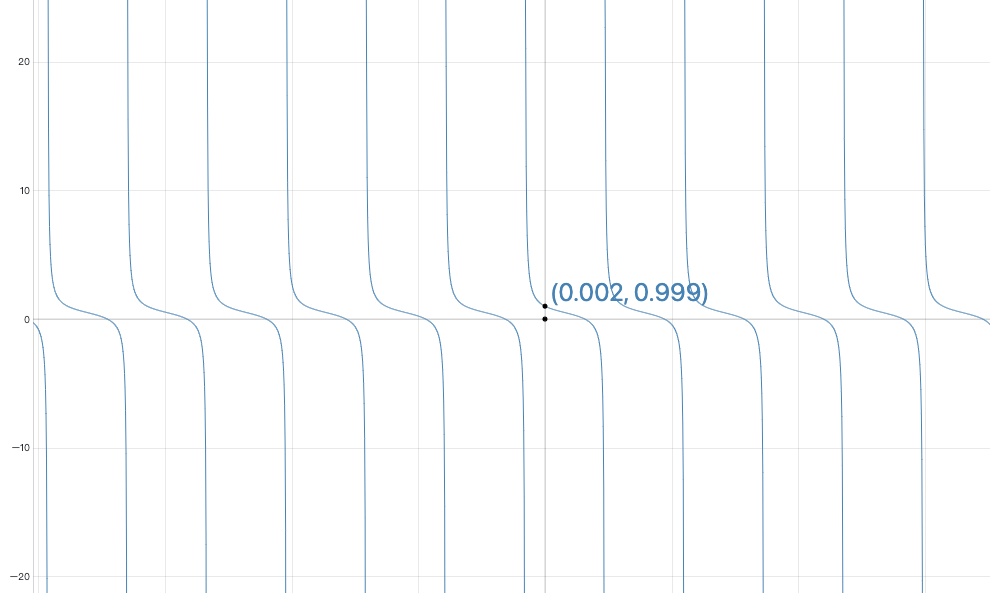

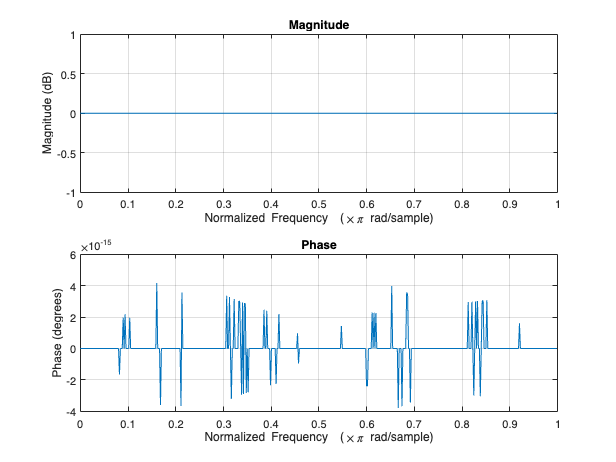

dw = 0

flag = logical
   0


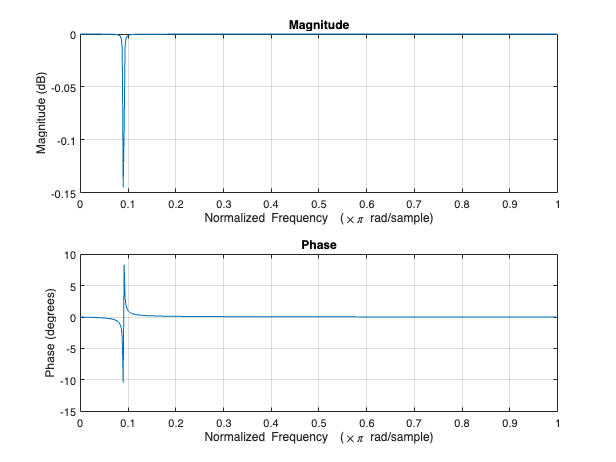

dw = 1.0000e-03

flag = logical
   1


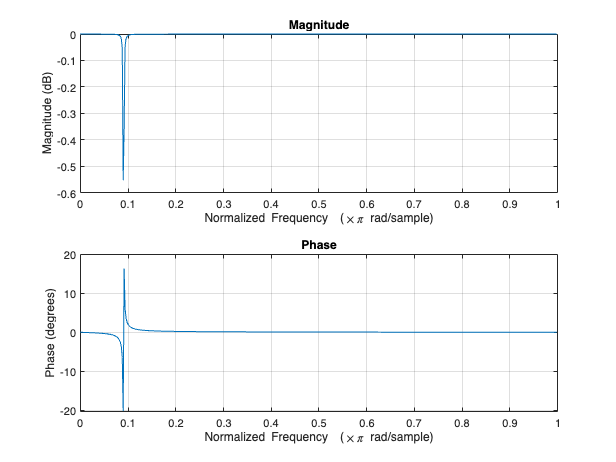

dw = 0.0020

flag = logical
   1


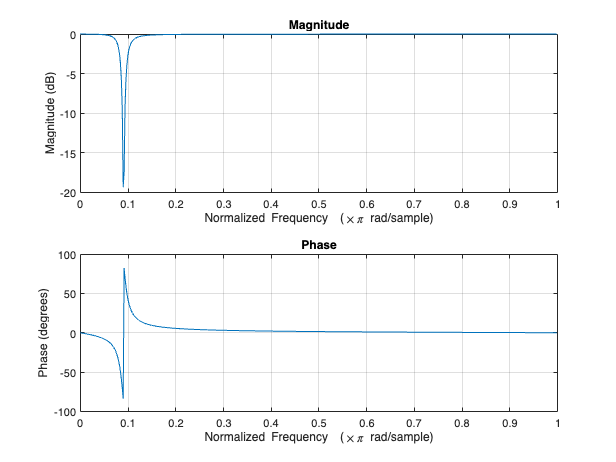

dw = 0.0500

flag = logical
   1


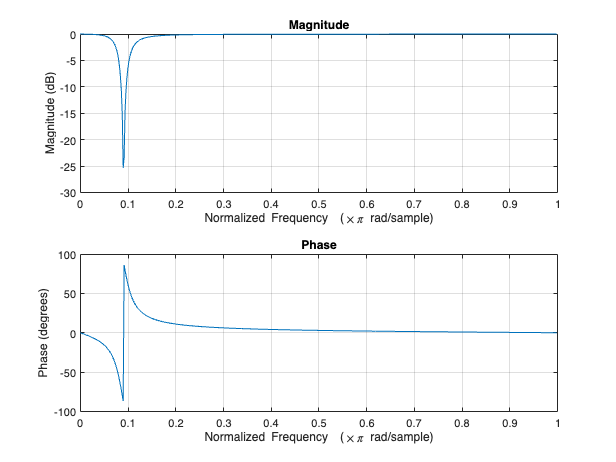

dw = 0.1000

flag = logical
   1


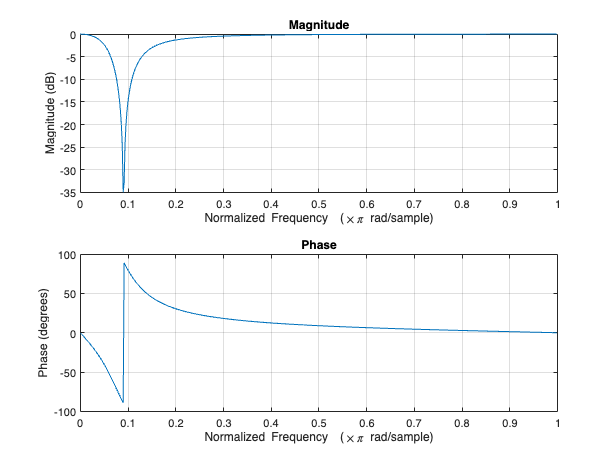

dw = 0.3000

flag = logical
   1


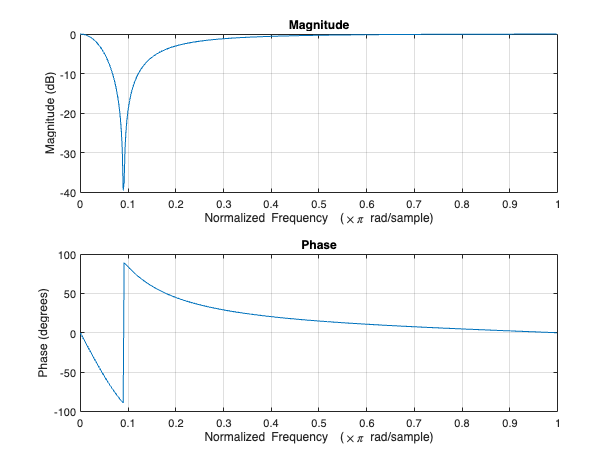

dw = 0.5000

flag = logical
   1


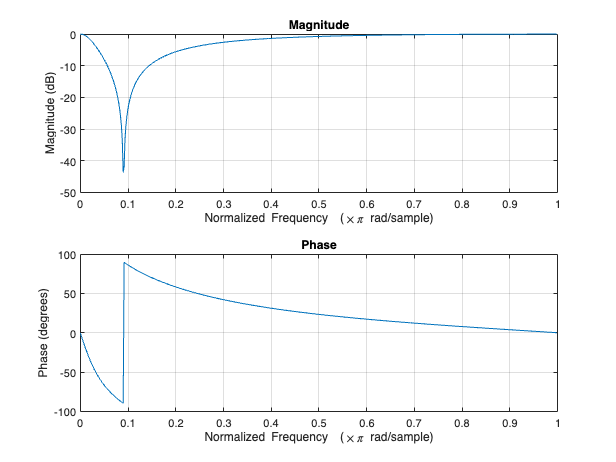

dw = 0.7854

flag = logical
   1


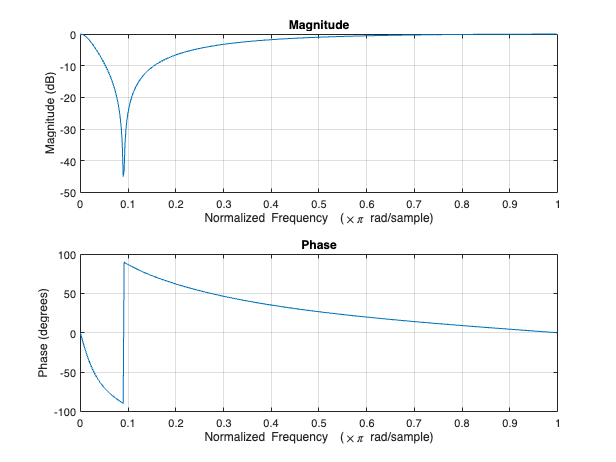

dw = 0.9000

flag = logical
   1


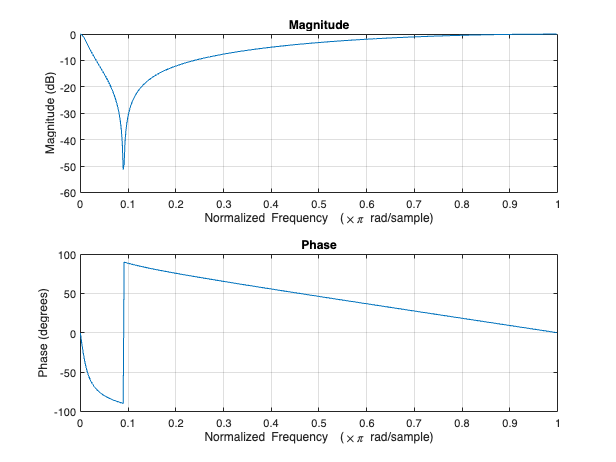

dw = 1.5708

flag = logical
   1


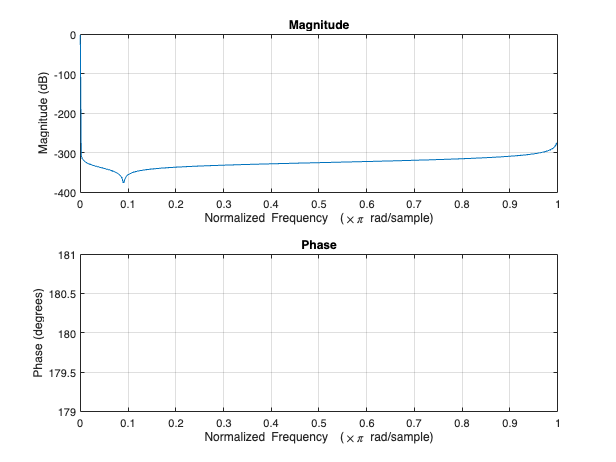

dw = 3.1416

flag = logical
   0


notch_b = b * [1, -2*cos(w_0) ,1]; %numeratora
notch_a = [1, -2*b*cos(w_0), 2*b-1]; %denominator 
for dw = [0 0.001 0.002 0.05 0.1 0.3 0.5 pi/4 0.9 pi/2 pi]
    b = 1/(1+tan(dw/2));
    notch_b = b * [1, -2*cos(w_0) ,1] ; %numerator
    notch_a = [1, -2*b*cos(w_0), 2*b-1]; %denominator 
    figure 
    freqz(notch_b,notch_a)
    dw
    flag = isstable(notch_b,notch_a)
end

% dw shoule be (0,pi)
dw = 1;
b = 1/(1+tan(dw/2));
mu = 0.1;
for k=1:N
    %%%% sng-sng LMS %%%%% to get optimized b
    %ADAPTIVE HOWLING CANCELLER USING ADAPTIVE IIR NOTCH FILTER: SIMULATION AND IMPLIMENTATION 
    %W. Leotwassana, R. Punchalard, and K Silaphan  
    notch_b = b * [1, -2*cos(w_0) ,1]; %numerator
    notch_a = [1, -2*b*cos(w_0), 2*b-1]; %denominator 
    W = [notch_b,-notch_a(2:3)]'; % notch filter coefficients
    y(k+2) = [x(k+2) x(k+1) x(k) y(k+1) y(k)] * W;%convolution with filter coefficients
    y(k+2) = min(2, y(k+2));  %amplitude clipping
    y(k+2) = max(-2, y(k+2));
    w = [1 (-0.95)]';
    g = [y(k+2) x(k+2)] * w; %g(n) is the gradient signal, g>0 the signal is increasing
%     dw = dw - mu * sign(sign(abs(y(k+1))-abs(y(k)))*g); % dw decrease , filter is with less amplitue
    dw = dw - mu * sign(g); % dw decrease , filter is with less amplitue
    dw = min(dw,pi/2);
    dw = max(dw, 0.1);
    dw_value(k) = dw;
    b = 1/(1+tan(dw/2));
end
% mu = 0.01;
% for k=1:N
%     w = [1 (-0.95)]';
%     g = [x(k+1) y(k+1)] * w;
%     %%%% sng-sng LMS %%%%% to get optimized b
%     %ADAPTIVE HOWLING CANCELLER USING ADAPTIVE IIR NOTCH FILTER: SIMULATION AND IMPLIMENTATION 
%     %W. Leotwassana, R. Punchalard, and K Silaphan 
%     b = b - mu * sign(sign(y(k+2))*g);
%     notch_b = b * [1, -2*cos(w_0) ,1]; %numerator
%     notch_a = [1, -2*b*cos(w_0), 2*b-1]; %denominator 
%     W = [notch_b,notch_a(2:3)]'; % notch filter coefficients
%     y(k+2) = [x(k+2) x(k+1) x(k) y(k+1) y(k)] * W;%convolution with filter coefficients
% end
filtered_signal=y;
y_n_2 = y(end-1); %the one before last, y(n-2)
y_n_1 = y(end); %last sample , y(n-1)



## SFM Frequency band divide

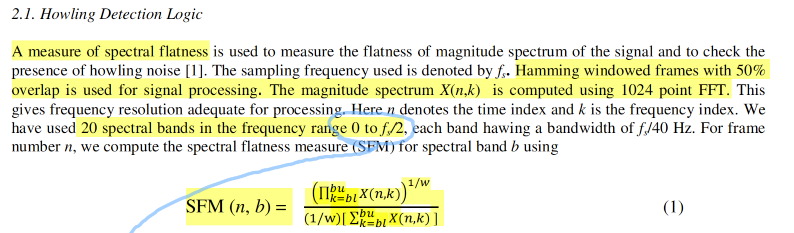

clear;clc;
% load speech signal 
cd '/Users/zhouyiliang/Desktop/work/'
% [speech,fs_old] = audioread('sound_sample/speech_x_1.wav');
[speech,fs_old] = audioread('sound_sample/speech_x_2.wav');
[speech,fs_old] = audioread('sound_sample/speech_add_howling_tre2000Hz800Hz2000Hz.wav');
% resample
fs = 16000;
y = resample(speech,fs,fs_old);
% y = y(1601:3200);
% cd '/Users/zhouyiliang/Desktop/work/sound_output'
% audiowrite('speech_16kHz_add_howling_tre2000Hz800Hz2000Hz.wav',y,fs)

## frame by frame processing

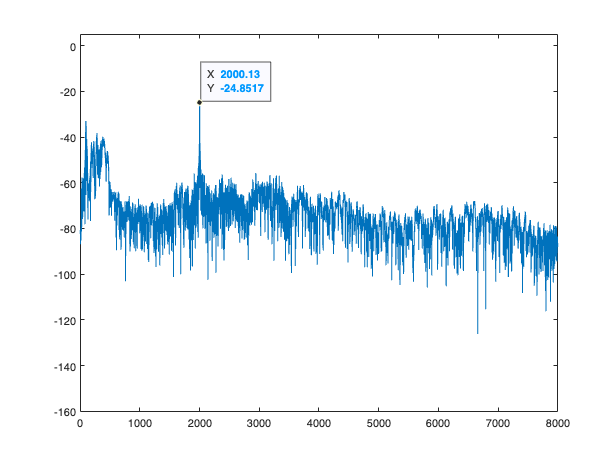

nfft = 16000;
% frame = abs(fft(y,nfft))*2/nfft;
frame = abs(fft(y,nfft));
% frame = abs(fft(y,nfft))*fs/nfft; %scale

% frame_doubleside = abs(fft(y,nfft));
% frame_doubleside = frame_doubleside / nfft; % weighting according to fft length
% frame = frame_doubleside(1:nfft/2+1); % only take single sided spectrum
% frame(2:end-1) = 2*frame(2:end-1); % weight by factor of 2 (do not weight 0 Hz and fs/2, they only exist once!)

 % bandwidth how many sample point in a band
f_all = linspace(0, fs, nfft);
w = 400/fs*nfft;
figure 
% plot(f_all,db(frame)); 
plot(f_all,db(frame*2/nfft)); 
xlim([0 fs/2])
ylim([-160 5])
ax = gca;
chart = ax.Children(1);
datatip(chart,2000,-8.435);
datatip(chart,2000,-8.435);
datatip(chart,2000,-8.435);
datatip(chart,2000,-8.435);

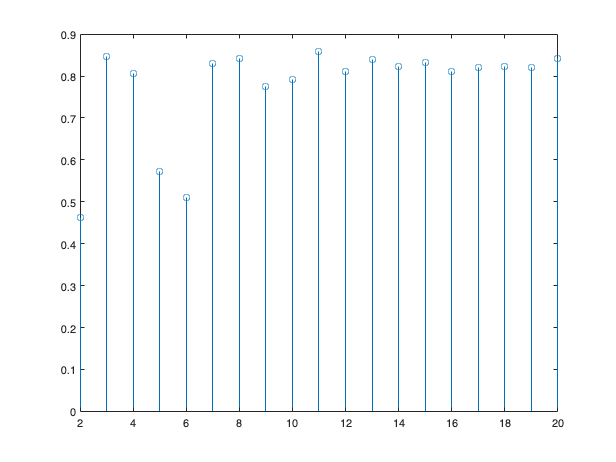

f_all = linspace(0, fs, nfft);
f_center = (linspace(200,7800,20))';
f_lower_upper = [(f_center-200) (f_center+200)];
threshold = 0.5;
howling_band =[];
counter=1;
SFM_in_band = zeros(20,1);
for b = 1:20 % loop for 20 bands
    indexes = find(f_all >= f_lower_upper(b,1) & f_all< f_lower_upper(b,2));
    if isempty(indexes) 
        SFM_in_band(b) = 1; % default value is 1, if howling value should be smaller
        counter=counter+1;
    else
        numerator = (prod(frame(indexes)))^(1/w); % product of all spectrums in the band
        denominator = (1/w) * sum(frame( indexes ));% sum of all spectrums in the band
        SFM_in_band(b) = numerator/denominator; % result of full spectrum
%%%%%%%%%% Howling in a band b is marked by a flag updated as %%%%%%%%%%
        if SFM_in_band(b) < threshold
            howling_band = [howling_band,b];
        end
    end
end

figure 
stem(SFM_in_band)

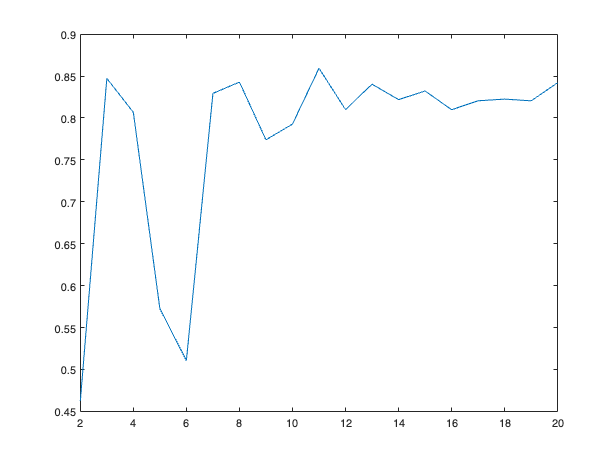

plot(SFM_in_band)